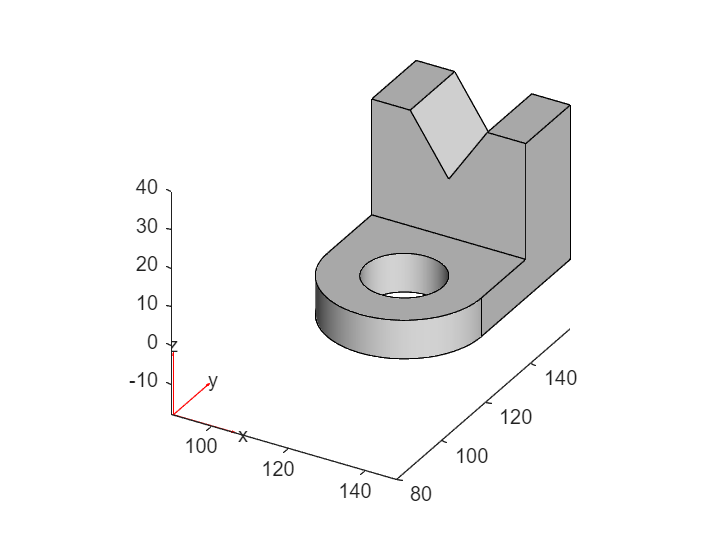

gm = importGeometry("FEM.stl");
pdegplot(gm)

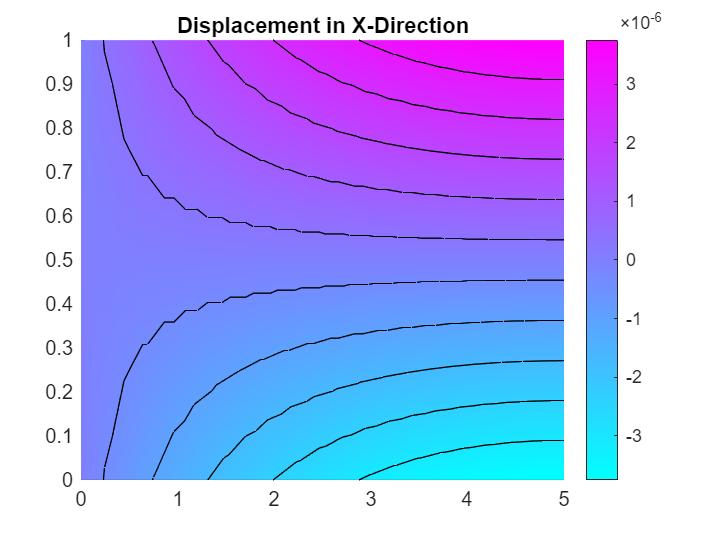

% Step 1: Create PDE model
pdeModel = createpde("structural","static-planestress");

% Step 2: Define geometry (rectangle)
rect = [3; 4; 0; 5; 5; 0; 0; 0; 1; 1];
g = decsg(rect);
geometryFromEdges(pdeModel, g);

% Step 3: Specify material properties
structuralProperties(pdeModel, 'YoungsModulus', 200e9, 'PoissonsRatio', 0.3);

% Step 4: Apply boundary conditions
structuralBC(pdeModel, 'Edge', 4, 'Constraint', 'fixed'); % Fixed support on left edge
structuralBoundaryLoad(pdeModel, 'Edge', 2, 'SurfaceTraction', [0; -1e4]); % Load on top edge

% Step 5: Generate mesh
generateMesh(pdeModel, 'Hmax', 0.5);

% Step 6: Solve the problem
result = solve(pdeModel);

% Step 7: Post-processing
figure;
pdeplot(pdeModel, 'XYData', result.Displacement.ux, 'Contour', 'on');
title('Displacement in X-Direction');

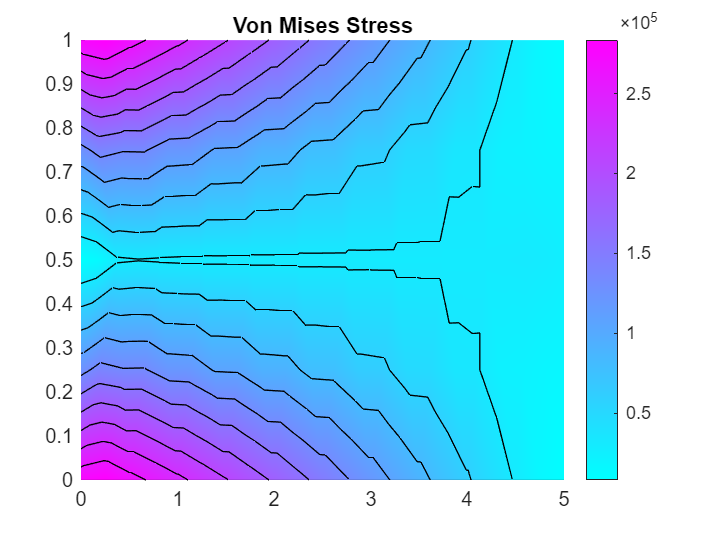


figure;
pdeplot(pdeModel, 'XYData', result.VonMisesStress, 'Contour', 'on');
title('Von Mises Stress');

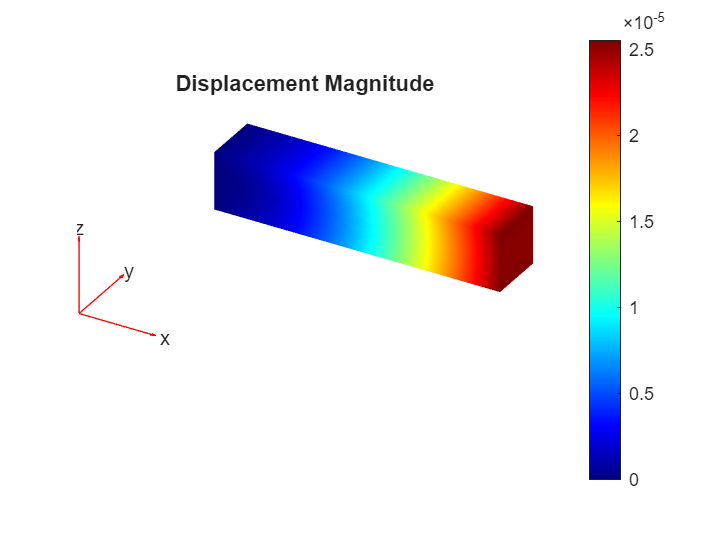

% Step 1: Create a PDE model for 3D structural analysis
pdeModel = createpde("structural", "static-solid");

% Step 2: Define the 3D geometry (a rectangular block)
% Create a block with dimensions 5x1x1 (length x height x width)
gm = multicuboid(5, 1, 1); % Length = 5, Height = 1, Width = 1
pdeModel.Geometry = gm;

% Step 3: Specify material properties (steel)
structuralProperties(pdeModel, 'YoungsModulus', 200e9, 'PoissonsRatio', 0.3);

% Step 4: Apply boundary conditions
% Fixed support on the left face (Face 5)
structuralBC(pdeModel, 'Face', 5, 'Constraint', 'fixed');

% Distributed load on the top face (Face 3)
structuralBoundaryLoad(pdeModel, 'Face', 3, 'SurfaceTraction', [0; 0; -1e4]); % Load in negative Z-direction

% Step 5: Generate mesh
generateMesh(pdeModel, 'Hmax', 0.5); % Hmax controls the mesh size

% Step 6: Solve the problem
result = solve(pdeModel);

% Step 7: Post-processing and visualization
% Plot displacement magnitude
figure;
pdeplot3D(pdeModel, 'ColorMapData', result.Displacement.Magnitude);
title('Displacement Magnitude');
xlabel('X');
ylabel('Y');
zlabel('Z');
colorbar;

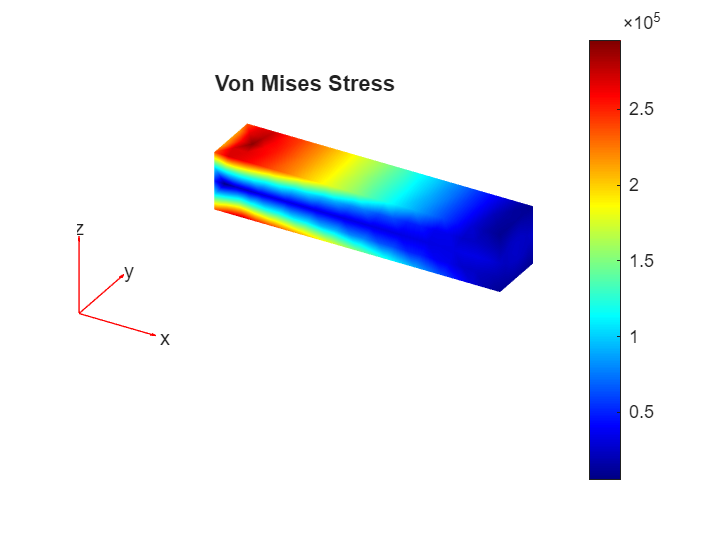


% Plot von Mises stress
figure;
pdeplot3D(pdeModel, 'ColorMapData', result.VonMisesStress);
title('Von Mises Stress');
xlabel('X');
ylabel('Y');
zlabel('Z');
colorbar;